     1



Altura maxima 2512.95 m 
 

Distancia recorride 4687.24 m 
 

Velocidad antes de impacto 8.52 m/s // 30.68 km/h


     2



Altura maxima 63.68 m 
 

Distancia recorride 118.77 m 
 

Velocidad antes de impacto 0.43 m/s // 1.56 km/h


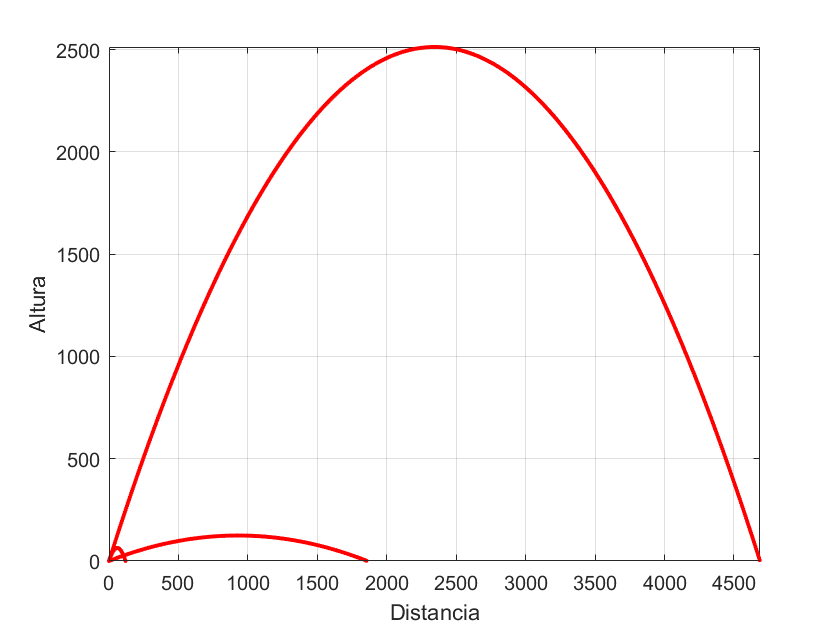

     3



Altura maxima 124.55 m 
 

Distancia recorride 1859.38 m 
 

Velocidad antes de impacto 2.80 m/s // 10.09 km/h


g=9.81;
ymaxmax=0;
xmaxmax=0;
for c=1:3
    vi=randi([2,300]);
    a=randi([10,70]);
    vix=vi*(cosd(a));
    viy=vi*(sind(a));
    xmax1 = (vix)*(2*viy)/g;
    xmax2 = ((vi^2)*2*(cosd(a)*sind(a)))/g;
    xmax3 = (2*vix*viy)/g;
    ymax=(viy^2)/(2*g);
    if ymax>ymaxmax
        ymaxmax=ymax;
    end
    if xmax1>xmax2 && xmax1>xmax3
        xmax=xmax1;
    elseif xmax2>xmax1 && xmax2>xmax3
        xmax=xmax2;
    else
        xmax=xmax3;
    end
    if xmax>xmaxmax
        xmaxmax=xmax;
    end
    tiempo=(2*viy)/g;
    for t=0:0.05:tiempo
       x=vix*t;
       y=viy*t-1/2*g*t^2;
       plot(x,y,'.r');
       xlabel('Distancia');
       ylabel('Altura');
       xlim([0,xmaxmax])
       ylim([0,ymaxmax])
       pause(0.0000001)
       hold on;
       grid on;
    end
    vf=viy*tiempo-1/2*g*t^2;
    xline(0);
    yline(0);
    disp(c);
    fprintf('Altura maxima %4.2f m \n ',ymax);
    fprintf('Distancia recorride %4.2f m \n ',xmax);
    fprintf('Velocidad antes de impacto %4.2f m/s // %4.2f km/h\n',vf,vf*3.6);
    fprintf('')
end